# Aircraft-to-Satellite Communication for ADS-B Out

This example examines the Automatic Dependent Surveillance–Broadcast (ADS-B) Out connectivity of a flight from Bucharest Henri Coanda Intl Airport to JFK New York Airport . The ADS-B Out system can connect to a variety of targets including airports and the Iridium NEXT satellite constellation. As a result, even while the aircraft does not have a direct line of sight with any ground station due to the Earth curvature over open water, the satellite ADS-B connection allows the aircraft to still provide continuous attitude, GPS position, and status to all other aircraft and airports interested in the aircraft state. The ADS-B Out system responds to the strongest ADS-B update initiator. The omnidirectional antennas on the top and bottom of the aircraft broadcast out to initiate the ADS-B update. 

This example consists of three main parts:

- Create the scenario containing an aircraft, airports, and Iridium satellite network.

- Perform access analysis to determine when the aircraft has line-of-sight access with the airports or satellites within the Iridium network.

- Perform link closure analysis of the ADS-B Out system with the airports and the satellites. 

This example uses:

- Satellite Communications Toolbox [satelliteScenario](docid:satcom_ref#mw_faac6a67-2a0c-429c-ae44-b010f8e0d376) object to analyze and visualize the results for the satellite, aircraft, and ground station. 

- (Optionally) You can also create [satelliteScenario](docid:aerotbx_ug#mw_faac6a67-2a0c-429c-ae44-b010f8e0d376) object using Aerospace Toolbox.

- Satellite Communications Toolbox [link](docid:satcom_ref#mw_47c652d3-a0be-463a-b44c-1839e5028769) and [linkIntervals](docid:satcom_ref#mw_2976f61e-effd-49be-9d06-59053b63ead3) functions to determine communications links.

- (Optionally) Phased Array System Toolbox [phased.CustomAntennaElement](docid:phased_ref#bsulx3i) functions to approximate the 48-beam antenna pattern of the Iridium satellite.

For more information on the Iridium NEXT satellite constellation and network, see [https://www.iridium.com/network/](https://www.iridium.com/network/). 

## Create Scenario

Create a satellite scenario. Specify a start date and duration for the scenario. Set the duration to equal to the flight time from New York to Bermuda, approximately 2 hours.

clear all;
close all;
clc;
startTime = datetime(2026,4,9,15,55,0,TimeZone="Pacific/Auckland");
stopTime = startTime + hours(3) + minutes(50);
sampleTime = 10;                                      %seconds
sc = satelliteScenario(startTime,stopTime,sampleTime);
viewer = satelliteScenarioViewer(sc);

### Airports

Set the airport properties to use in the scenario.

airportName = ["Wellington International Airport (Wellington)";...
    "Sydney Kingsford Smith Airport (Sydney)"];
airportLat = [-41.3272; -33.9548];
airportLon = [174.8052;151.1897];

Add the airports to the scenario using the [groundStation](docid:satcom_ref#mw_fc4b43ff-2e6c-4339-a0af-5701c0fb16fc) function.

airports = groundStation(sc,airportLat,airportLon,Name=airportName);

### Aircraft

Create a [geoTrajectory](docid:fusion_ref#sysobj_geo_trajectory) System object™  from a set of waypoints and arrival times typical of a flight, taking off from Wellington International Airport and landing at Sydney Kingsford Smith Airport. The `geoTrajectory` System object generates trajectories based on waypoints in geodetic coordinates. Set the flight time based on the scenario duration.

waypoints = [... % Latitude (deg), Longitude (deg), Altitude (meters) 

    -41.3272, 174.8052,    4;...   % Takeoff - Wellington NZWN elevation ~4m
    -41.4088,  174.7811,  609;...
    -41.4424, 174.7494, 1219;...
    -41.4298, 174.6538, 1828;...
    -35.9324,  155.2361, 11582;...
    -35.3403,  154.2447, 11582;...   % Cruise altitude reached
     -35.1915, 153.9896, 11277;...
    -35.0398, 153.7313 ,11277;...
    -34.8009, 153.3287,11582;...
    -34.3358, 152.5571,8229;...
    -34.0329, 152.0384,5181;...   % Top of descent
    -34.0017, 151.8044, 3657;...
    -33.7669, 151.4050, 1524;...
    -33.7430, 151.1863, 914;...
    -33.7626, 151.1639,  914;...
    -33.9548, 151.1897,    6];     % Landing - Sydney YSSY elevation ~6m

timeOfArrival = duration([... % time (HH:mm:ss)
   "00:00:00";...
    "00:03:00";...
    "00:08:00";...
    "00:14:00";...
    "00:21:00";...
    "00:28:00";...
    "01:05:00";...
    "01:42:00";...
    "02:18:00";...
    "02:50:00";...
    "03:10:00";...
    "03:22:00";...
    "03:32:00";...
    "03:40:00";...
    "03:46:00";...
    "03:50:00"]);

trajectory = geoTrajectory(waypoints,seconds(timeOfArrival),AutoPitch=true,AutoBank=true);

Output the latitude, longitude, and altitude (LLA) waypoints of the aircraft trajectory at the sample rate of the scenario.

LLA = lookupPose(trajectory,0:sc.SampleTime:max(seconds(timeOfArrival)));

Visualize the aircraft trajectory using [geoplot](docid:matlab_ref#mw_72cdff48-e02c-4af9-9960-1bacb7aa52c5).

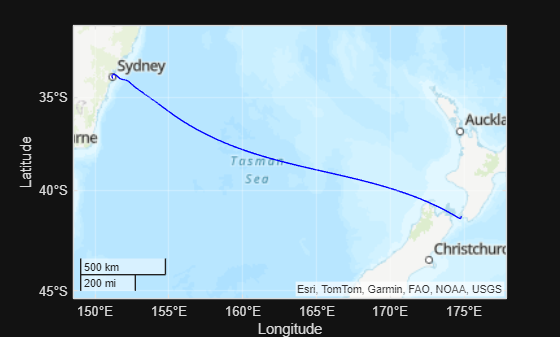

geoplot(LLA(:,1), LLA(:,2), "b-")
geolimits([-40 -32],[170 150])
geobasemap topographic;

geolimits([-45.4 -30.9],[148.5 177.9])

Add the aircraft to the scenario using the [`platform`](docid:satcom_ref#mw_31a459a2-269e-4b33-977a-b6d51f2d9dd5) function. The `platform` function allows you to add platforms, such as aircraft, cars, or ships, to the scenario and perform access analysis with satellites, ground stations, and other platforms. Use the `Visual3DModel` property to add a visual representation of the aircraft to the scenario. For this example, use the NarrowBodyAirliner`.glb` file.

aircraft = platform(sc,trajectory, Name="Aircraft", Visual3DModel="NarrowBodyAirliner.glb");
camtarget(viewer,aircraft);

Invalid or deleted object.

Error in matlabshared.satellitescenario.Viewer/get.IsDynamic

Error in matlabshared.satellitescenario.Viewer/camtarget

 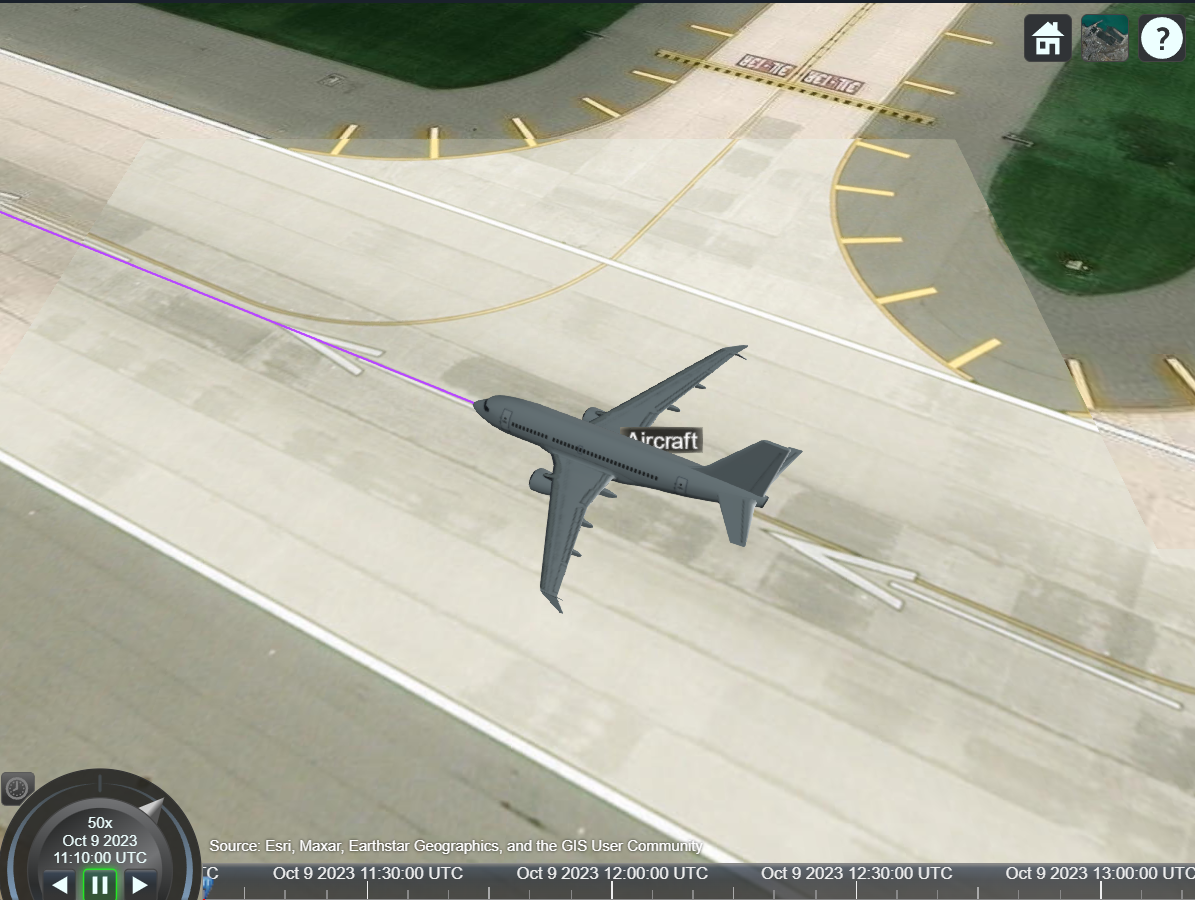

### Satellites

The Iridium NEXT satellite network, launched between 2018 and 2019 [1], contains 66 active LEO satellites with:

- Six orbital planes with an approximate inclination of 86.6 degrees and difference of RAAN of approximately 30 degrees between planes [1].

- 11 satellites per orbital plane with an approximate difference in true anomaly of 32.7 degrees between satellites [1].  

Add the active Iridium NEXT satellites to the scenario. Create the orbital elements for the satellites in the Iridium network and create the satellites using the [satellite](docid:satcom_ref#mw_427deb16-c8f5-45f0-b17e-bbc94abc36b8) function.

numSatellitesPerOrbitalPlane = 11;
numOrbits = 6;

orbitIdx = repelem(1:numOrbits,1,numSatellitesPerOrbitalPlane);
planeIdx = repmat(1:numSatellitesPerOrbitalPlane,1,numOrbits);

RAAN = 180*(orbitIdx-1)/numOrbits;
trueanomaly = 360*(planeIdx-1 + 0.5*(mod(orbitIdx,2)-1))/numSatellitesPerOrbitalPlane;
semimajoraxis = repmat((6371 + 780)*1e3,size(RAAN)); % meters
inclination = repmat(86.4,size(RAAN)); % degrees
eccentricity = zeros(size(RAAN)); % degrees
argofperiapsis = zeros(size(RAAN)); % degrees

iridiumSatellites = satellite(sc,...
    semimajoraxis,eccentricity,inclination,RAAN,argofperiapsis,trueanomaly,...
    Name="Iridium " + string(1:66)');

If you have a license for Aerospace Toolbox, you can also create the Iridium constellation using the [walkerStar](docid:aerotbx_ug#mw_4807e7ac-66d3-488e-9f4c-bd244a5ade4a) function.

As many satellites share common orbital planes, display the orbital path of only the first satellite in each plane.

hide(iridiumSatellites.Orbit,viewer);
show(iridiumSatellites(1:numSatellitesPerOrbitalPlane:end).Orbit,viewer);

Add conical sensors to the Iridium satellites to act as cameras to establish visual access between the satellites and the aircraft.

iridiumConicalSensors = conicalSensor(iridiumSatellites,"MaxViewAngle",125);

## Aircraft Access Analysis

Determine access analysis between the aircraft, airports, and satellites using the scenario. Calculate the access interval between the aircraft and airports using the [access](docid:satcom_ref#mw_aeb231b0-be89-4f06-a15d-9628350a5fc6) and [accessIntervals](docid:satcom_ref#mw_2b564569-fdb8-447e-9055-fba4fde2bdc9) functions based on when the aircraft has line-of-sight access to the airport. JFK and L.F. Wade airports can see the aircraft during the first and last two hours of the flight, respectively. Otherwise the aircraft is blocked by the curvature of the Earth.

acAirport = access(aircraft,sc.GroundStations);
airportAccessIntvls = accessIntervals(acAirport)

airportAccessIntvls = 2×8 table
      Source                          Target                         IntervalNumber         StartTime                EndTime           Duration    StartOrbit    EndOrbit
    __________    _______________________________________________    ______________    ____________________    ____________________    ________    __________    ________

    "Aircraft"    "Wellington International Airport (Wellington)"          1           09-Apr-2026 03:55:00    09-Apr-2026 04:10:20       920         NaN          NaN   
    "Aircraft"    "Sydney Kingsford Smith Airport (Sydney)"                1           09-Apr-2026 04:17:50    09-Apr-2026 07:45:00     12430         NaN          NaN   


Calculate a similar access analysis between the aircraft and the satellites based on the visibility of the aircraft within the conical sensors' field of view. This serves as a first-round approximation of the Iridium multi-beam antenna shown in the next section. The dashed lines in the viewer show the line-of-sight access from the aircraft body to the airports and satellites.

acSatellite = access(aircraft,iridiumConicalSensors);
satelliteAccessIntvls = accessIntervals(acSatellite);

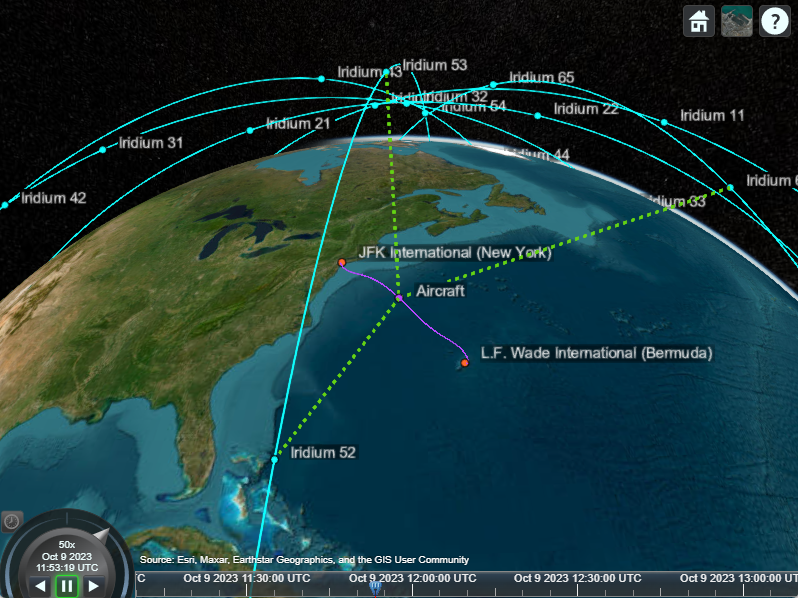

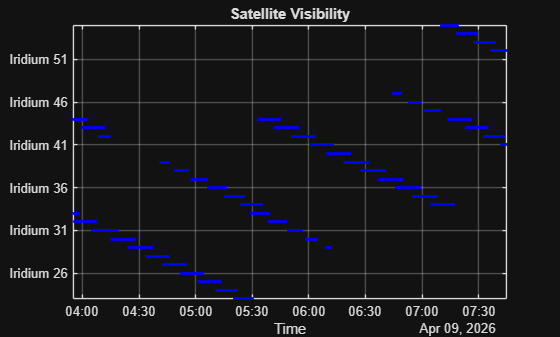

[sSatellite,time] = accessStatus(acSatellite); 
satVisPlotData = double(sSatellite);
satVisPlotData(satVisPlotData == false) = NaN; % Hide invisible satellites.
satVisPlotData = satVisPlotData + (0:numel(iridiumSatellites)-1)'; % Add space to satellites to be stacked.

plot(time,satVisPlotData," .",Color="blue")
yticks(1:5:66)
yticklabels(iridiumSatellites.Name(1:5:66))
title("Satellite Visibility")
grid on
xlabel("Time")
axis tight

The access intervals computation shows that the aircraft has continuous satellite communication access with the Iridium network when the aircraft is over the open ocean. Combined with the airport access, the aircraft has continuous line-of-sight access throughout the flight.

## Aircraft Link Analysis

After establishing that the aircraft maintains a direct connection with either airports and the Iridium network throughout the flight, generate a link budget for the respective ground and satellite-based ADS-B Out systems. The ADS-B Out system uses the existing Mode A/C and S transponder antennas located on the top and bottom of the aircraft, respectively. ADS-B uses the Mode S of the transponder and operates the ADS-B Out on a frequency of 1090 MHz with a minimum effective isotropic radiated power (EIRP) of 125 Watts.

fADSB = 1090e6; % 1090 MHz

For this example, model the pair of Mode-S transponders as a single isotropic transmitter located near the top-front of the aircraft. The mounting location corresponds to the approximate location of the top mounted ADS-B transceiver on a typical commercial aircraft. Since an isotropic antenna has an effective gain of 0 dBi, setting the transmission amplifier power output to 125 Watts also results in a radiated power from the antenna of 125 Watts.

aircraftADSBAntenna = arrayConfig("Size",[1 1]); % Create an isotropic antenna element

aircraftADSBTransmitter = transmitter(aircraft, ...
    Antenna = aircraftADSBAntenna, ...
    Frequency = fADSB,...
    Power=10*log10(125),...     % ADS-B Out minimum as EIRP of 125 Watts
    MountingLocation=[8,0,-2.7],...
    Name="ADS-B Aircraft Transmitter");

### Aircraft to Airport ADS-B Out Link

Add isotropic antennas and receivers to the airports.

% Airport Antenna 
airportADSBAntenna = arrayConfig("Size",[1 1]); % Create an isotropic antenna element
airportADSBReceiver = receiver(...
    airports, ...
    Antenna=airportADSBAntenna, ...    
    Name=airports.Name + " Receiver");
pattern(airportADSBReceiver,fADSB,Size=1000);

### Aircraft to Satellite ADS-B Out Link

Using Satellite Communication Toolbox, you can model the antenna on the Iridium satellite as an isotropic antenna. If you have a license for Phased Array System Toolbox, you can model an approximation of the custom 48-beam antenna used by the Iridium NEXT satellites [2]. Use the drop-down list to select the antenna to model. The solid lines in the viewer show viable links from the aircraft antenna to the airports and satellites.

antennaType = "Isotropic";

#### Simulate Iridium Satellites Link with Isotropic Antennas

Create and add an isotropic antenna receiver to the Iridium satellites.

if antennaType == "Isotropic"
    % Create and add an isotropic antenna receiver to the Iridium satellites.
    satelliteADSBAntenna = arrayConfig("Size",[1 1]); % Add code comment    
    satelliteADSBReceiver = receiver(iridiumSatellites, ...
        Antenna=satelliteADSBAntenna, ...
        MountingAngles=[0,0,0], ...
        Name=iridiumSatellites.Name + " Receiver");
    pattern(satelliteADSBReceiver,fADSB,Size=50000);    

    % Play the scenario.
    play(sc);
end

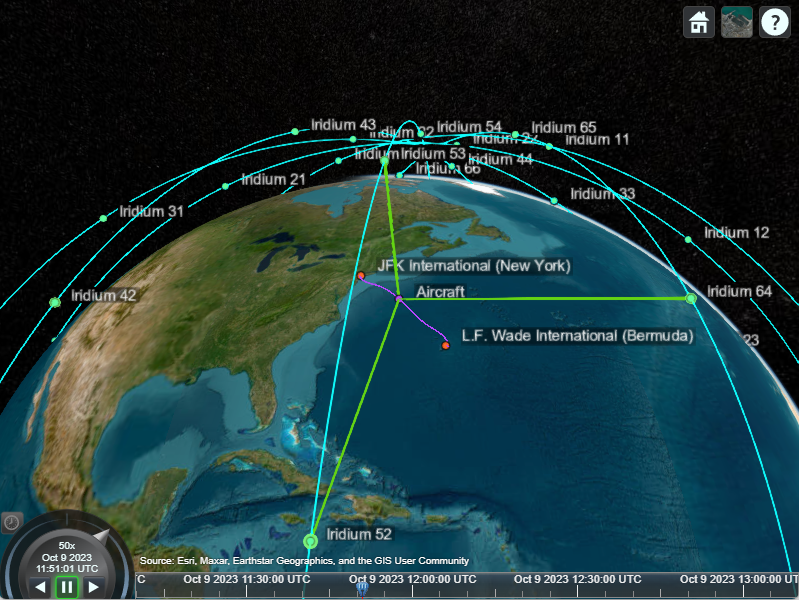

#### Simulate Iridium Satellites Link with Custom 48-Beam Antenna

Create and add a custom antenna element receiver to the Iridium satellites using the **HelperCustom48BeamAntenna** convenience function.

Note: The mounting angle matches the default frames of Phased Array System Toolbox and the Satellite Communications Toolbox. 

if antennaType == "Custom 48-Beam"
    % Use Custom Antenna Element on 48-spot beam    
    satelliteADSBAntenna = HelperCustom48BeamAntenna(fADSB);
    satelliteADSBReceiver = receiver(iridiumSatellites, ...
        Antenna=satelliteADSBAntenna, ...
        MountingAngles=[0,-90,0], ...
        Name=iridiumSatellites.Name + " Receiver");
    pattern(satelliteADSBReceiver,fADSB,Size=200000);    

    % Play the scenario.
    play(sc);
end

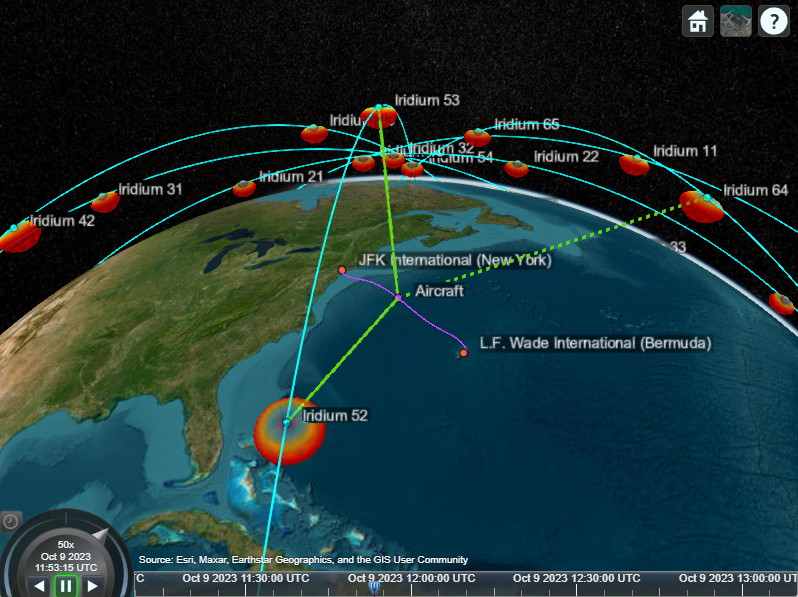

### ADS-B Out Link Closure Times

Add ADS-B Out link analysis from the aircraft to airports and satellites.

lnkADSB = link(aircraftADSBTransmitter, [airportADSBReceiver, satelliteADSBReceiver]);

Plot the maximum margin for the link to any of the available receivers. The margin is the received Eb/No minus the required Eb/No for that receiver.

[eL,time] = ebno(lnkADSB);
marginADSB = eL - repmat([airportADSBReceiver.RequiredEbNo,satelliteADSBReceiver.RequiredEbNo]',[1,size(eL,2)]);
figure;
plot(time,max(marginADSB),"b")
axis tight
grid on
xlabel("Time");
ylabel("Margin (dB)");
title("ADS-B Out Link Margin vs. Time");

## Aircraft Chase View

Optionally, create a second viewer to follow or chase the aircraft and visualize the access and links relative to the aircraft body. The mouse can then be used to adjust the view of the aircraft as shown in the image.

aircraftViewer = satelliteScenarioViewer(sc);
aircraftViewer.Position = aircraftViewer.Position + [200 200 0 0]; % Reposition aircraft viewer
aircraftViewer.PlaybackSpeedMultiplier = 5;
aircraftViewer.play();
camtarget(aircraftViewer,aircraft);

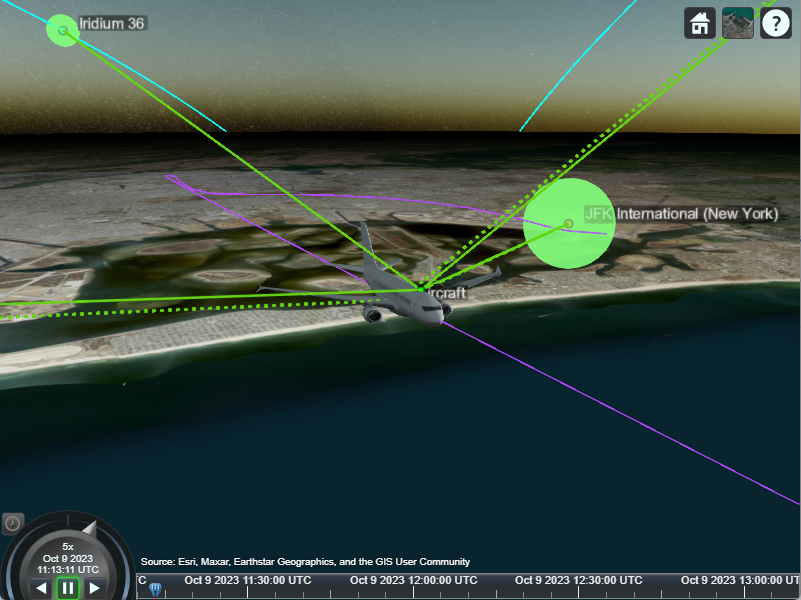

## References

[1] *Attachment EngineeringStatement SAT-MOD-20131227-00148*. [https://fcc.report/IBFS/SAT-MOD-20131227-00148/1031348](https://fcc.report/IBFS/SAT-MOD-20131227-00148/1031348). Accessed 17 Jan. 2023.

[2] *Attachment Exhibit A SAT-MOD-20131227-00148*. [https://fcc.report/IBFS/SAT-MOD-20131227-00148/1031240](https://fcc.report/IBFS/SAT-MOD-20131227-00148/1031240). Accessed 17 Jan. 2023.

*Copyright 2022-2023 The MathWorks, Inc.*